
s = tf('s');

% element values:
L   = 560e-6;
C   = 100e-6;
rL  = 0.230;
Rb  = 10000;
Ra  = 10000;
Vg  = 10;
Vm  = 10.6;
R   = 25; 
D   = 0.5; 
Rc  = 100000;
Cc  = 22e-9;

% undetermined values:

Q   = sqrt(L * C) / (rL * C + (L / R))

Q = 5.2124

wo  = 1/sqrt(L * C)

wo = 4.2258e+03

f   = wo/(2*pi)

f = 672.5524

fl  = 10^(-1/(2*Q))*f

fl = 539.2636

fr  = 10^(1/(2*Q))*f

fr = 838.7859

wl  = 10^(-1/(2*Q))*wo

wl = 3.3883e+03

wr  = 10^(1/(2*Q))*wo

wr = 5.2702e+03

Ds  = (1 + (s / (wo * Q)) + ( s / (wo))^2 )

Ds =
 
  2.203e04 s^2 + 1.786e07 s + 3.933e11
  ------------------------------------
                3.933e11
 
Continuous-time transfer function.





% Given T.F's from Table 15.1
Gvd = Vg / Ds;
Gvg = D / Ds;
Gpwm= 1 /Vm;
Zout= rL *(1 + ((s * L) / rL) / Ds)

Zout =
 
  1165 s^2 + 5.161e07 s + 2.081e10
  --------------------------------
  5066 s^2 + 4.107e06 s + 9.047e10
 
Continuous-time transfer function.



H   = Rb / (Ra + Rb)

H = 0.5000


% Open loop and close loop
     Gc  = 1/ (Rc * Cc * s);
     T   = 1/Vm * Gc * Gvd * H

T =
 
                1.855e11
  -------------------------------------
  48.46 s^3 + 3.929e04 s^2 + 8.653e08 s
 
Continuous-time transfer function.



Gvref_CL = ( T / (1+T) ) / H

Gvref_CL =
 
                     8.991e12 s^3 + 7.289e15 s^2 + 1.605e20 s
  -------------------------------------------------------------------------------
  1174 s^6 + 1.904e06 s^5 + 4.27e10 s^4 + 3.849e13 s^3 + 3.78e17 s^2 + 8.027e19 s
 
Continuous-time transfer function.



  Gvg_CL = Gvg / (1 + T);
 Zout_CL = Zout / (1+ T);


## Task 1.a.i

A   = Vg*H/Vm

A = 0.4717

AQ  = A*Q

AQ = 2.4587

a   = -Q*180

a = -938.2329

20*log10(A)

ans = -6.5267

Ti  = 1/Vm *1*Gvd*H

Ti =
 
                1.855e11
  ------------------------------------
  2.203e04 s^2 + 1.786e07 s + 3.933e11
 
Continuous-time transfer function.



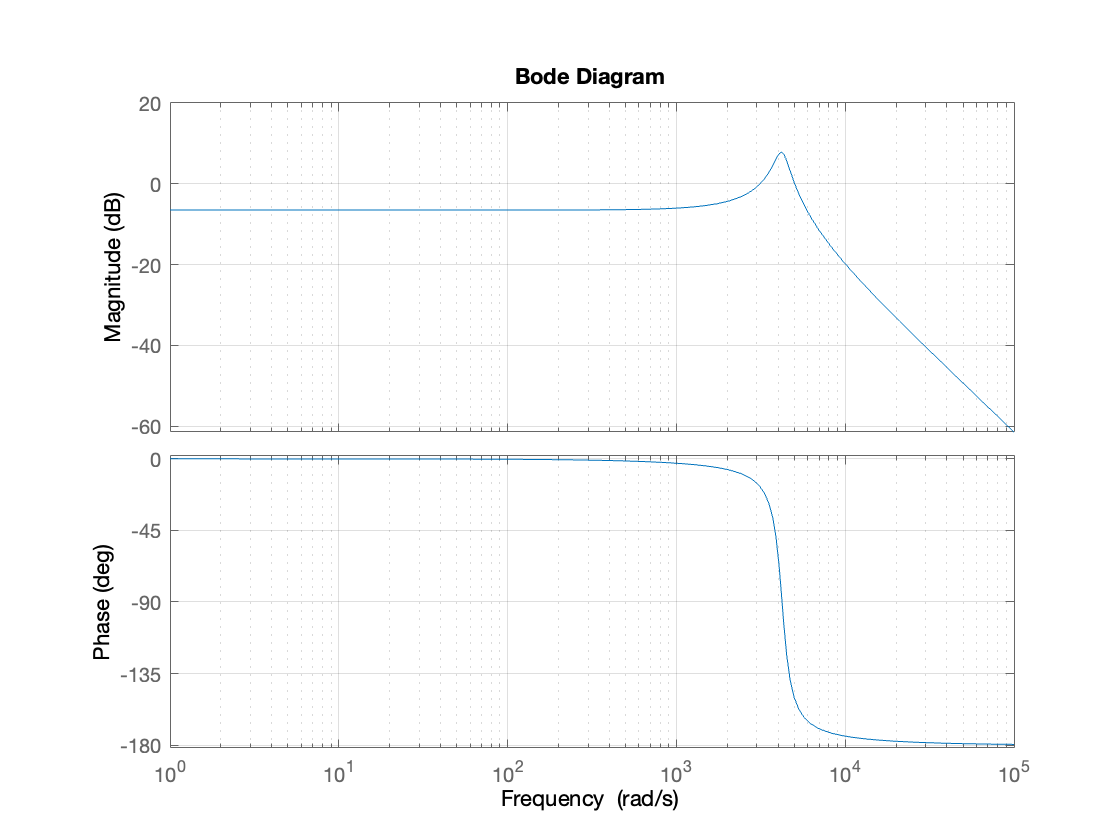


figure (1) 
bodeplot(Ti, {1,10e4})
grid on

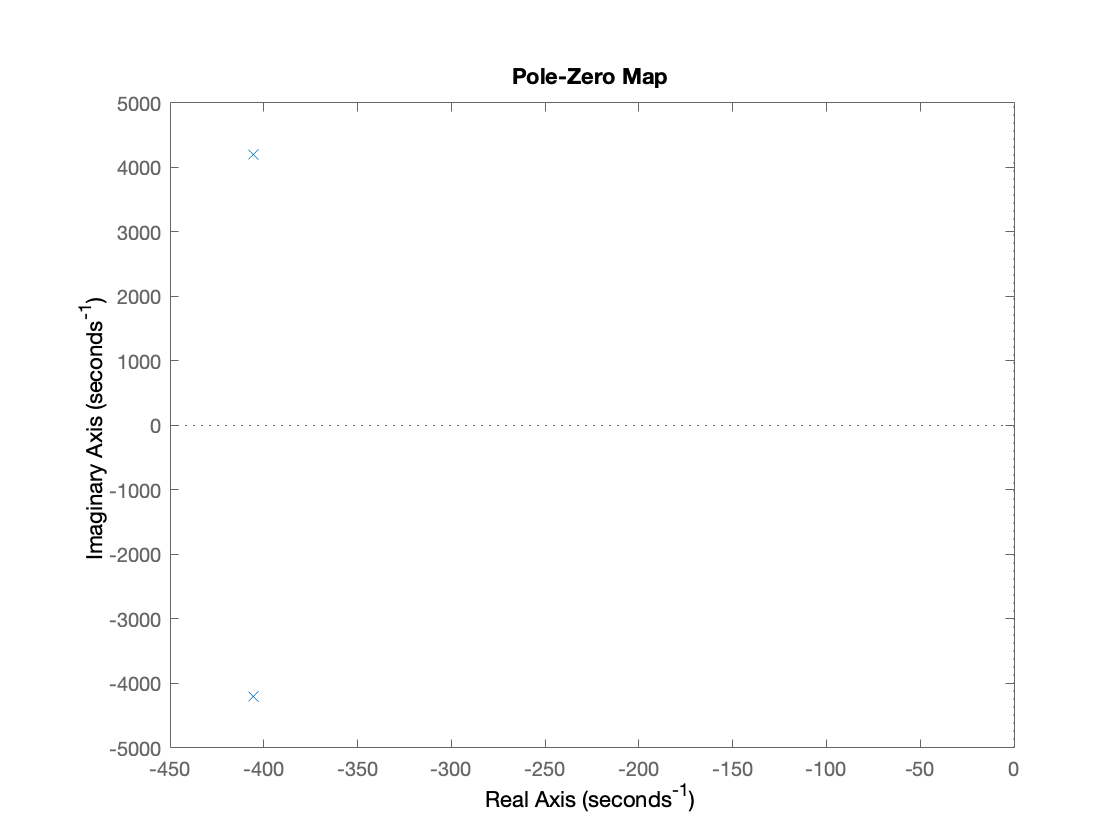

 
figure(2)
pzmap(Ti)

## Task 1.a.ii

Tii  = 1/Vm * Gc * Gvd * H

Tii =
 
                1.855e11
  -------------------------------------
  48.46 s^3 + 3.929e04 s^2 + 8.653e08 s
 
Continuous-time transfer function.




Ki = 1/(Rc*Cc)                   % 

Ki = 454.5455

MGc= 20*log10(Ki)                % origin magnitude

MGc = 53.1515

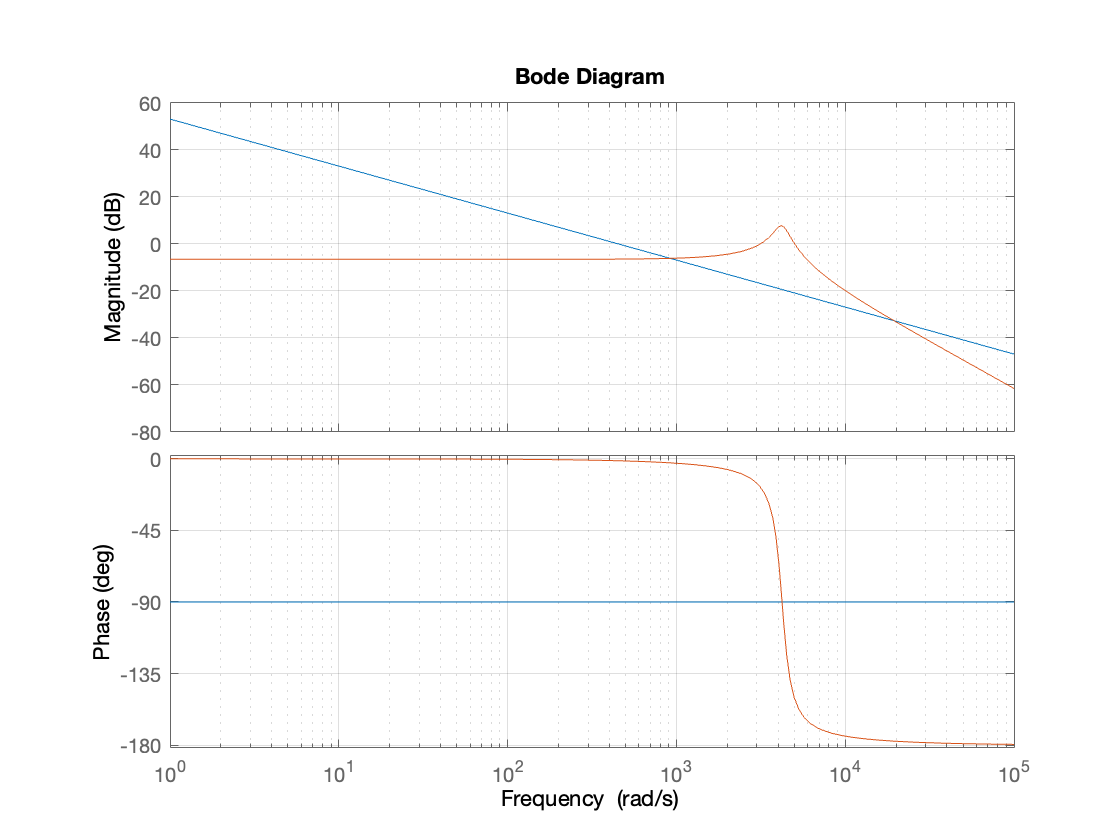

options = bodeoptions;
options.FreqUnits = 'Hz'; 
figure(1)
 bodeplot(Gc,Ti,{1,10e4})
 grid on

## Task 1.a.iii


Tii  = 1/Vm * Gc * Gvd * H

Tii =
 
                1.855e11
  -------------------------------------
  48.46 s^3 + 3.929e04 s^2 + 8.653e08 s
 
Continuous-time transfer function.



%pzplot(Tii,Ti)

fGM= f                  % Gain Margin frequency

fGM = 672.5524

GM = 20*log10(1/(L*Ki)) % Gain margin

GM = 11.8847

fPM= (A*Ki)/(2*pi)      % Phase Margin frequency 

fPM = 34.1241

%PM = 
STBLTY = Vm*(Ra+Rb*wo)/(Vg*Rb*Q)

STBLTY = 859.5605

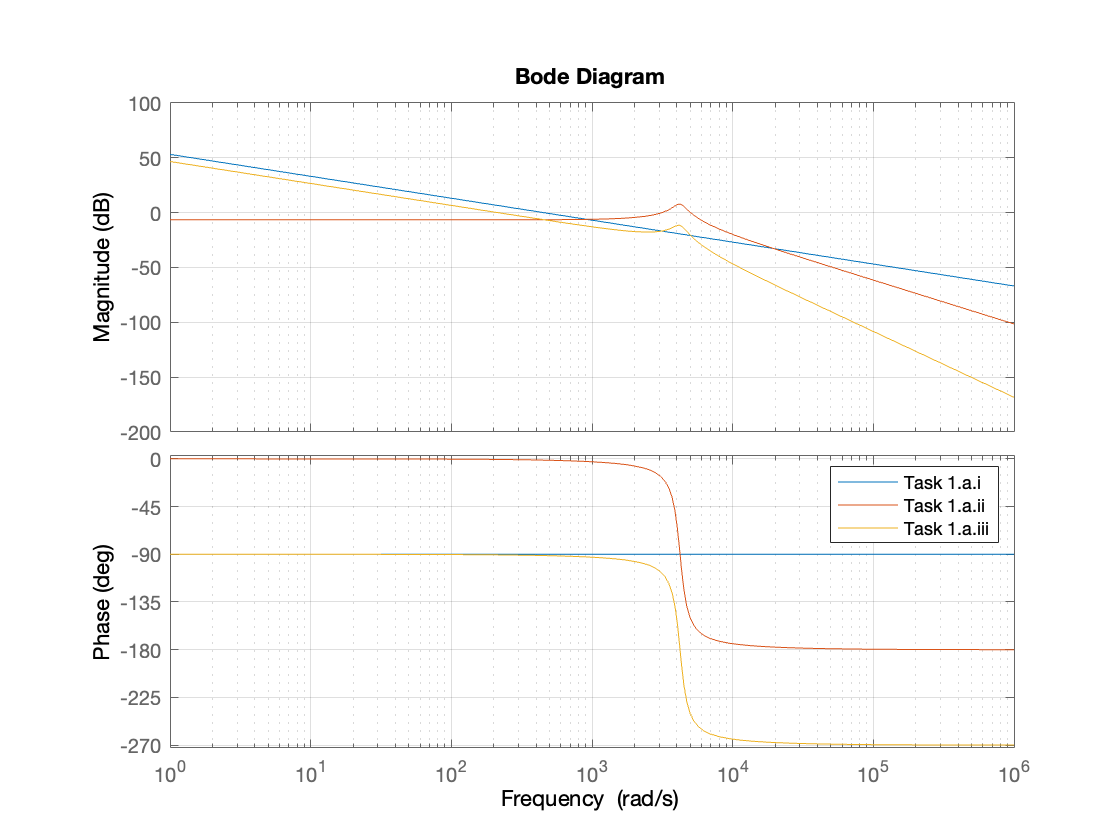


options = bodeoptions;
options.FreqUnits = 'Hz'; 
figure(1)
 bodeplot(Gc,Ti,Tii, {1,10e5})
 legend('Task 1.a.i', 'Task 1.a.ii', 'Task 1.a.iii')

 grid on

## Task 2.a. Bode plot for loop gain:

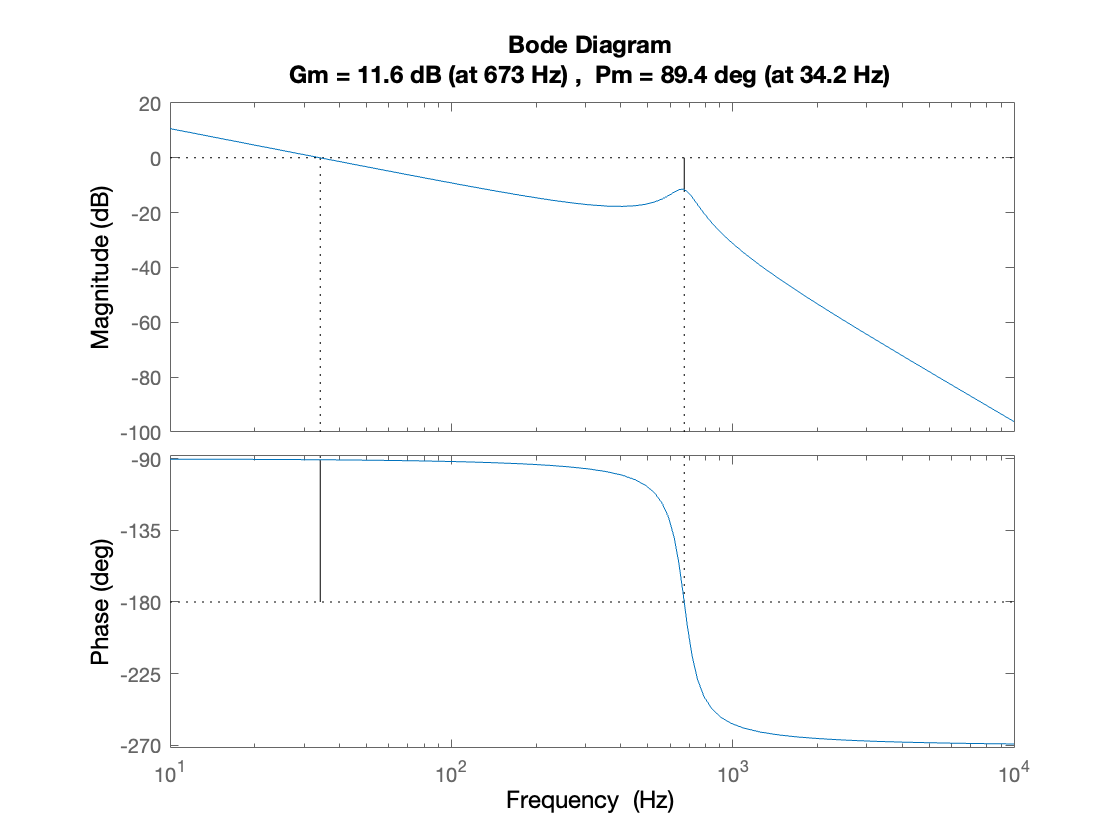


margin(Tii)

h=gcr;
h.AxesGrid.Xunits = 'Hz';
h.AxesGrid.TitleStyle.FontSize = 12;
h.AxesGrid.XLabelStyle.FontSize = 12;
h.AxesGrid.YLabelStyle.FontSize = 12;

## Task 2.b Input voltage to output voltage   

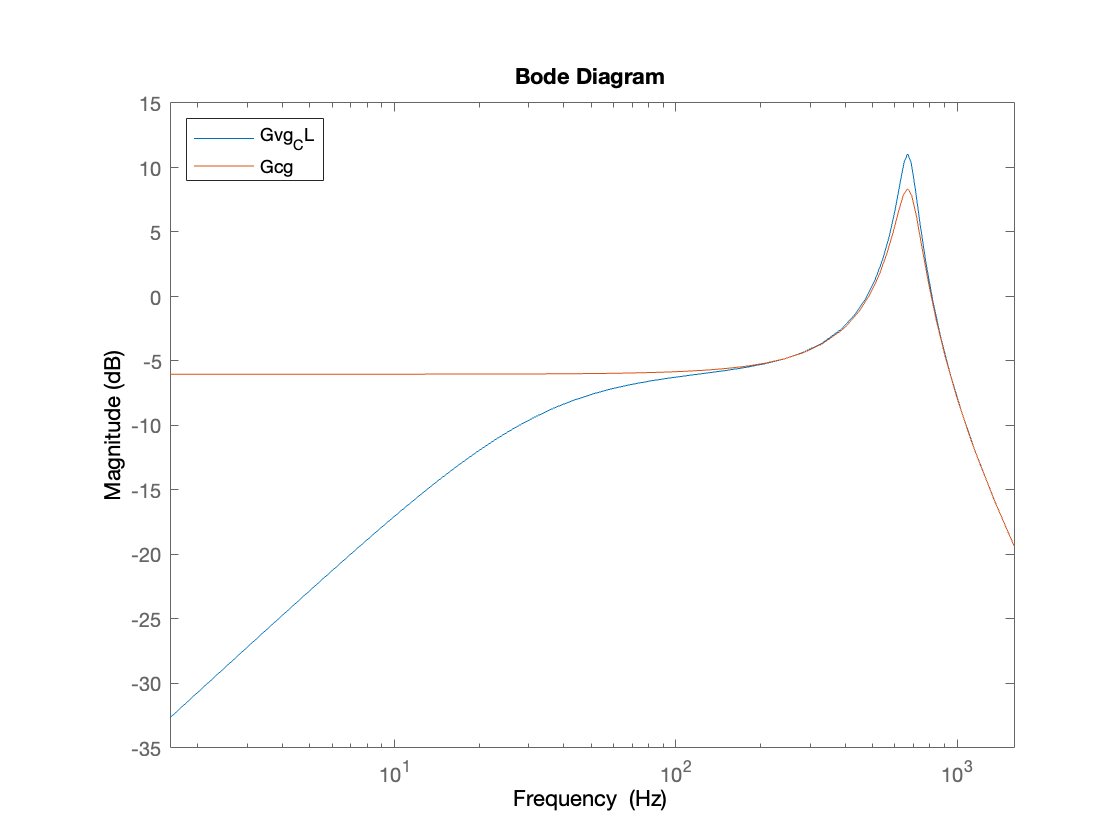

options = bodeoptions("cstprefs");
options.FreqUnits = 'Hz';
bodemag(Gvg_CL,Gvg,options,{10e0, 10e3})
legend('Gvg_CL','Gcg','Location','northwest')

## Task 2.c Output current to output voltage

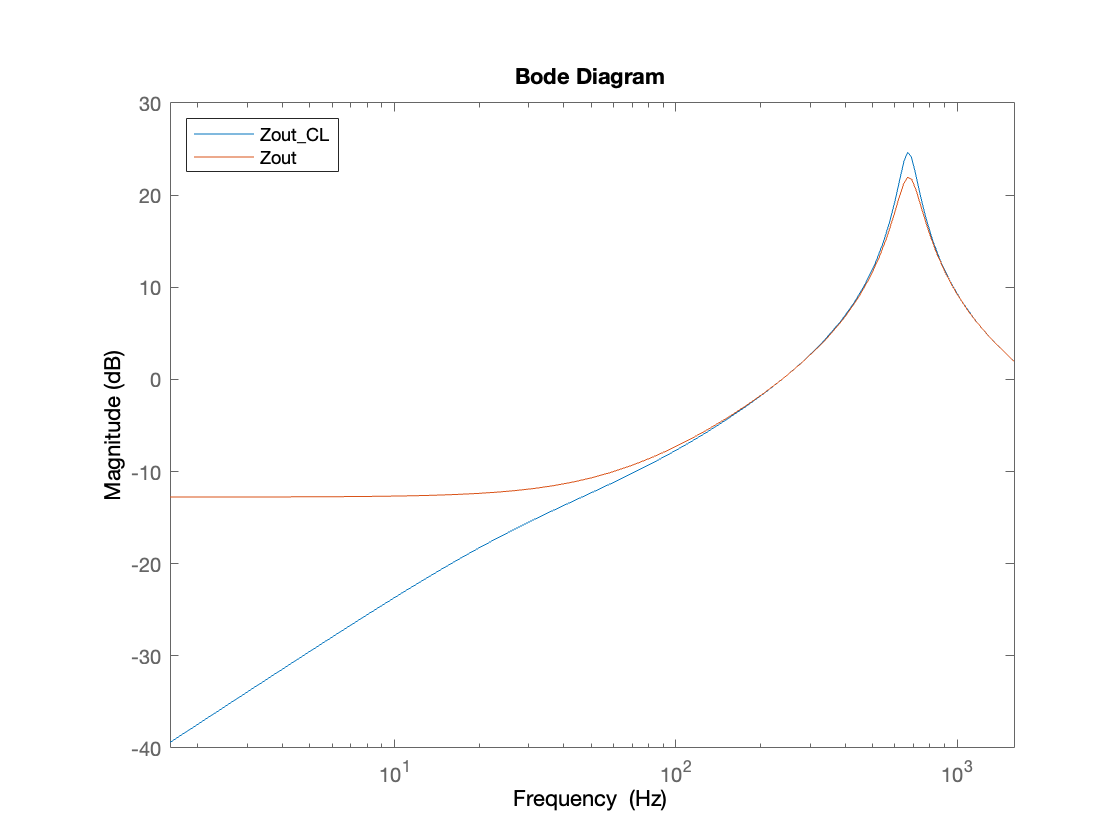

options = bodeoptions("cstprefs");
options.FreqUnits = 'Hz';
bodemag(-Zout_CL,Zout,options,{10e0, 10e3})
 legend('Zout_CL','Zout','Location','northwest')

## Task 3.a

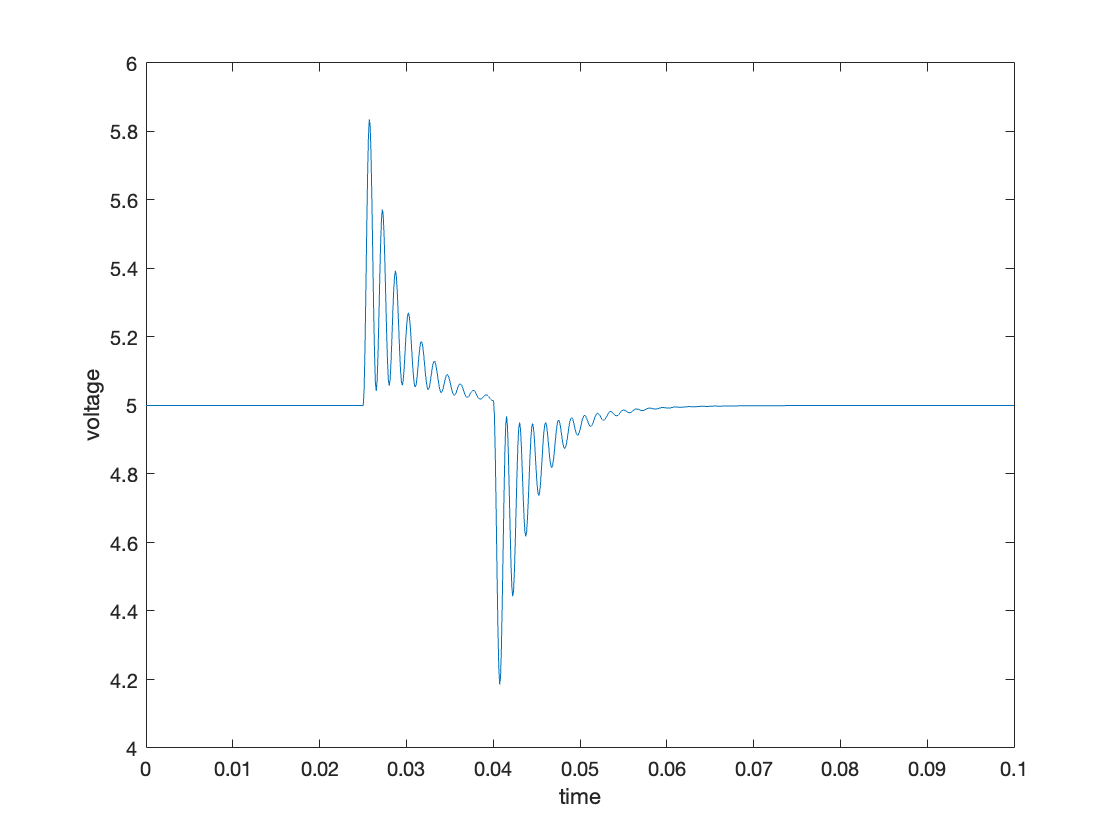

V = D*Vg;
t = linspace(0, .1, 1000);
u = zeros(size(t));
Vg_diff = 1;
ind = find(t>=.025 & t<=.04);
u(ind)= u(ind)+Vg_diff;
figure;
y = lsim(Gvg_CL, u, t);
plot(t,y+V)
xlabel('time')
ylabel('voltage')

del_v = max(y)-min(y)

del_v = 1.6504

SSE = y(ind(end))

SSE = 0.0143

## Task 3.b

I0_1    = V/25;
I0_2    = V/5;
I0_diff = I0_2-I0_1;
V       = D*Vg;
t       = linspace(0.02, .06, 1000);
u       = zeros(size(t));

ind     = find(t>=.025 & t<=.04);
u(ind)  = u(ind)+Vg_diff;
figure;
y       = lsim(-Zout_CL, u, t);

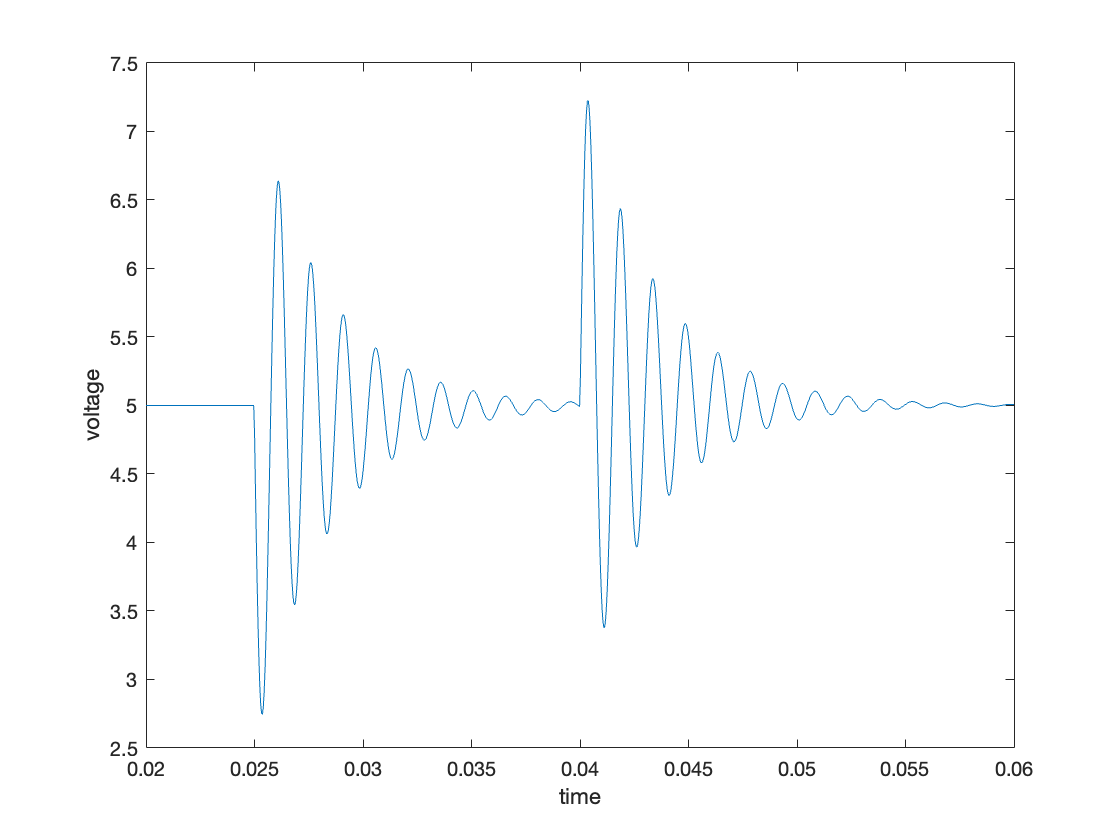

plot(t,y+V)
xlabel('time')
ylabel('voltage')

del_v = max(y)-min(y)

del_v = 4.4819

SSE = abs(y(ind(end)))

SSE = 0.0075